## Computing Event-Related Potentials (ERP) by averaging

***Activity time- and phase-locked to the event.***

Mathilde Marie Duville

**Notice 01: ***Parallel computing may be implemented to decrease computing time (in case of large datasets; the *Parallel Computing Toolbox must be installed*)*

**Notice 02: **The code for single-trial ERP extraction is also available in the next section

% mr = mapreducer();

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

*Import previously preprocessed data*

MainPath = pwd; folder = uigetdir(); 
fileList = dir(fullfile(folder, '*IClabel-Clean.set')); L=length(fileList); n = cell(1,L);
for i = 1:L

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part001-IClabel-Clean.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part001-IClabel-Clean.fdt'...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


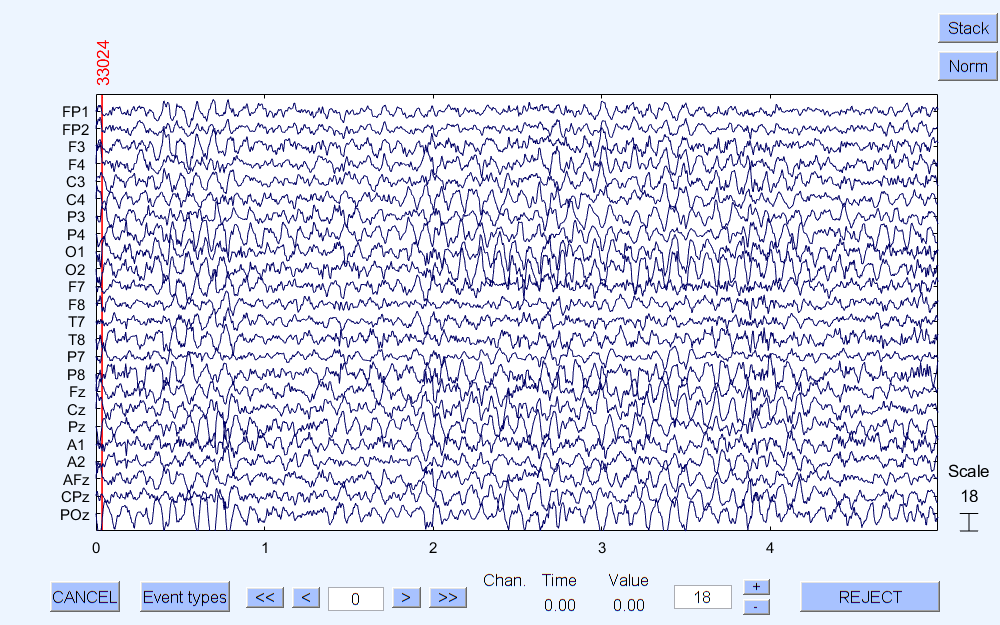

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part002-IClabel-Clean.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part002-IClabel-Clean.fdt'...


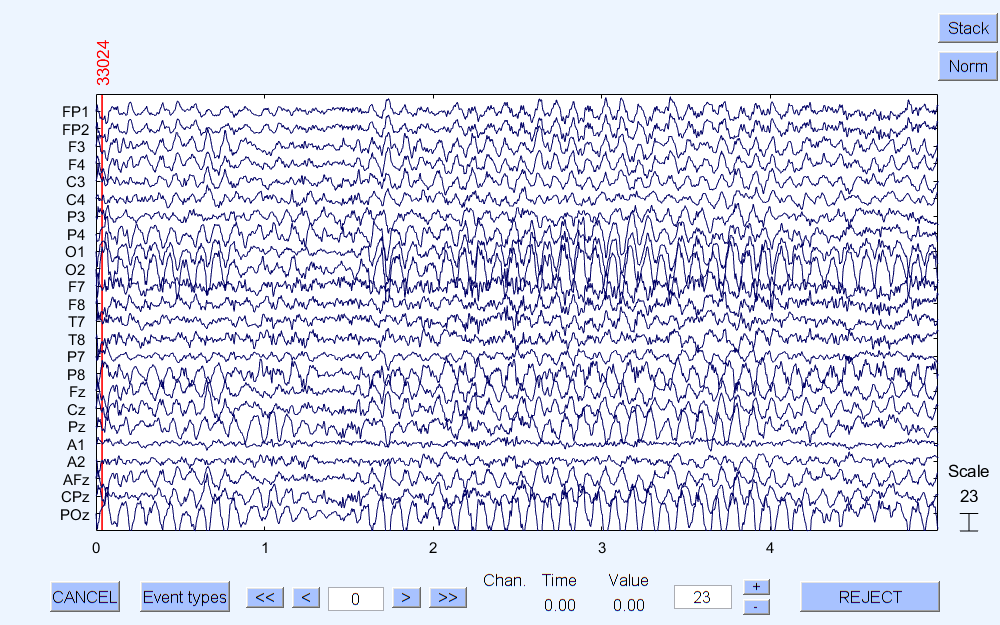

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part003-IClabel-Clean.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Part003-IClabel-Clean.fdt'...


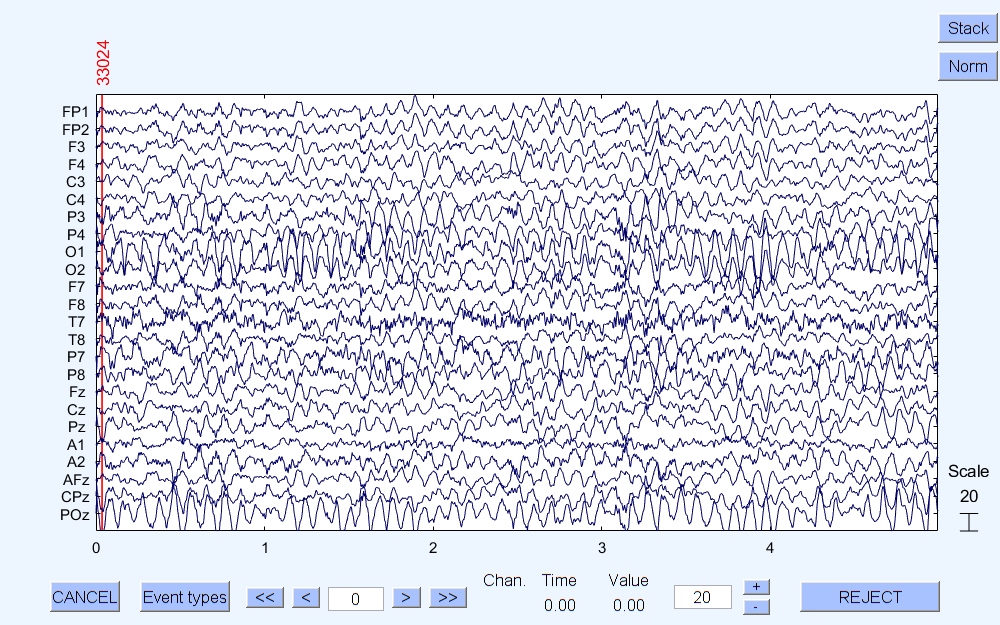

   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name;
   EEG = []; EEG = pop_loadset('filename', fileList(i).name, 'filepath', MainPath);
   EEG.setname = fileList(i).name; CURRENTSET = []; CURRENTSET = i; 
   [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
   pop_eegplot(EEG, 1, 1, 1); 
end
eeglab redraw

Define single trials based on markers (epochs). Also define the baseline for correction. Here a [-500;-200 ms] baseline is chosen. However, the longer the baseline the better, as it would favor the conservation of proportionality to the source activity and betwen channels.

Baseline correction helps to subtract away the activity of all sources (or components) that does not differ from a prior-to-event time window, highlighting the activity of the component of interest (the one that characterizes the processing of the event). 

However, subtraction may be associated with several drawbacks, such as: 

- Some before-event activity may not be “noisy”. Indeed, there may be some event-related activity before the apparition of the event, depending on the experimental paradigm, that may predict (or be correlated to) the activity before the apparition of the event (predicted coding model). It may not be recommended to subtract this activity from the post-event time-window of interest. 

- Subtracting a different baseline to each electrode may alienate the signal from the original source activity and reduce the proportionality (linearity) to it and between electrodes. 

Subtraction is generally implemented for time analysis. However, other methodology such as division, percentage of change of Z-transformation may be applied as sensitivity analyses for comparison to subtraction. 

Finally, you may choose the time-window of the baseline adequately. Dependending on the nature of the pre-stimulus period, you may prefer a time-window that most reflect a "rest period". Also, consider that because of prediction mechanisms, a time-window away from the apparition is better (when the participant is less disposed to start predicting, thus processing the event). Also, although not common, a baseline recorded at rest before or after the experimental procedure (nevertheless in similar conditions), may be considered. Notice that in this case, the baseline would be the same for all trials and would be longer. Thus, it would reduce between-trial biases, and would favor proportionality to the source activity and betwen channels.

**Also, other methods for source reconstruction, that do not require baseline correction, may be applied (Principal Component Analysis, Independent Component Analysis, Linear Discriminant Analysis Beamformer). Please, see section Single-Trial ERP. **

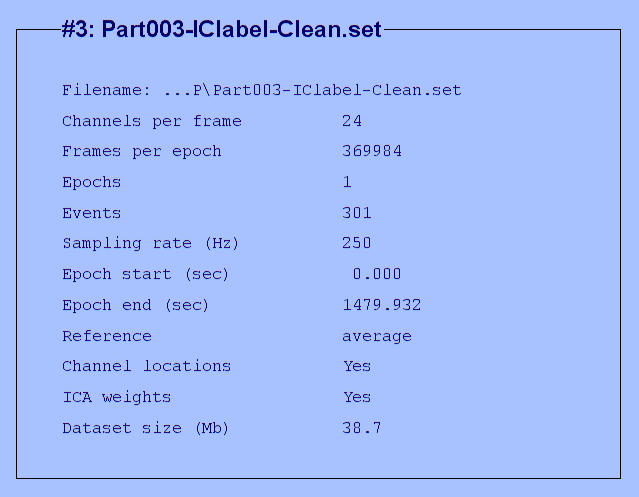

rmbase_lim1 = -500 ; rmbase_lim2 = -200; 

EEG_epoched = cell(1,L);

for i = 1:1:L
    EEG =[]; EEG = ALLEEG(i); [types] = eeg_eventtypes(EEG); 
    %Remove event of no interest for ERP extraction
    types(ismember(types,'33024')) = [];
    %Define epochs
    for j = 1:1:size(types,1) %number of onditions defined by the event
        try EEG_ep = pop_epoch(EEG, {types{j,1}}, [-0.5 1]);
            %Baseline correction   
            EEG_epc = pop_rmbase(EEG_ep, [rmbase_lim1 rmbase_lim2] ,[]);
            %Save epoched data in cell
            EEG_epoched{j,i} = EEG_epc;  %conditions x participants
        catch 
            disp('error')
        end
    end
end


pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


**Note:** because of too much computation load, only the data from one participant and one conidition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading.** 

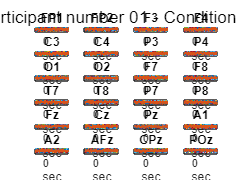

% Plot data per condition and file (participants)/each curve is a trial
% Don't run if too much conditions and participants
for k = 1:1:1%size(EEG_epoched,1) %conditions
    data = EEG_epoched(k,:); EEG_epoched(k,:) = data(~cellfun('isempty',EEG_epoched(k,:))); 
    labels = convertCharsToStrings({EEG.chanlocs.labels});
    for j = 1:1:1%size(EEG_epoched,2)
        figure("WindowState","maximized"); time = EEG_epoched{k,j}.times/1000; %time in sec
        for i = 1:1:EEG_epoched{k,j}.nbchan
            subplot(6,4,i)  %Adjust to the number of channels
            plot(time,squeeze(EEG_epoched{k,j}.data(i,:,:)), LineWidth=1.5)
            title([labels(i)]); 
    %         xlim([-0.5 1]);
            xlabel("sec"); ylabel("\muV")
        end
        sgtitle(['Participant number ', num2str(j,'%02.f'), ...
            ' - Condition ', num2str(k,'%02.f')])
    end
end

Average accross trials

ERP_av = cell(size(EEG_epoched,1),size(EEG_epoched,2));
for k = 1:1:size(EEG_epoched,1) %conditions
    for i = 1:1:size(EEG_epoched,2) %participants
        ERP_ep = [];
        try ERP_ep = mean(EEG_epoched{k,i}.data,3);
            % Save data 
            ERP_av{k,i} = ERP_ep;
        catch 
            disp('error')
        end
    end
end

**Note:** because of too much computation load, only the data from one participant and one conidition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

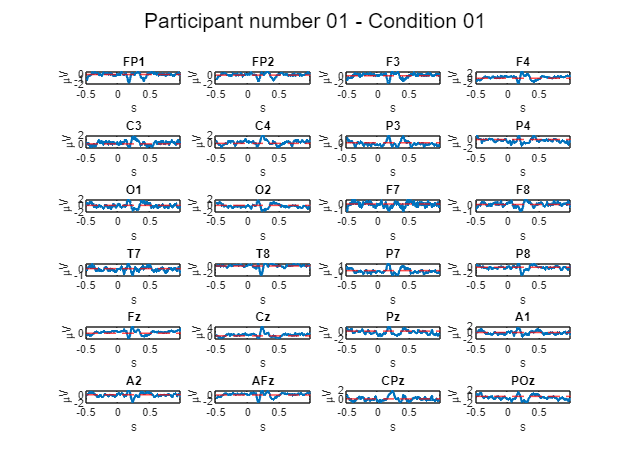

% Plot 
for k = 1:1:1%size(EEG_epoched,1) %conditions
    data = ERP_av(k,:); ERP_av(k,:) = data(~cellfun('isempty',ERP_av(k,:))); 
    for j = 1:1:1%size(ERP_av,2) %participants
        figure("WindowState","maximized")
        for i = 1:1:EEG_epoched{k,j}.nbchan
            subplot(6,4,i)  %Adjust to the number of channels
            plot(time,squeeze(ERP_av{k,j}(i,:)), LineWidth=1.5)
            title([labels(i)]); yline(0, "LineWidth",1, "LineStyle","--", "Color","red");
    %         xlim([-0.5 1]);
            xlabel("s"); ylabel("\muV")
        end
        sgtitle(['Participant number ', num2str(j,'%02.f'), ...
            ' - Condition ', num2str(k,'%02.f')])
    end
end

Average accross participants (grand average)

ERP_av_double=cell(size(ERP_av,1),1);
for k = 1:1:size(ERP_av,1) %conditions
    for i = 1:1:size(ERP_av,2) %participants
        ERP_av_double{k,:}(:,:,i) = cell2mat(ERP_av(k,i));
    end
end

ERP_GA=cell(size(ERP_av,1),1);
for k = 1:1:size(ERP_av_double,1) %conditions
    ERP_GA{k,1} = mean(ERP_av_double{k,:},3);
end

**Note:** because of too much computation load, only the data from one conidition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

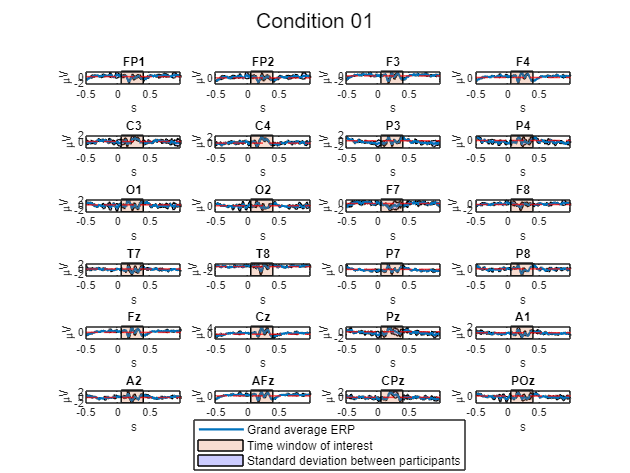

% Plot areas are standard deviations between participants
for k = 1:1:1%size(ERP_GA,1) %conditions
    figure("WindowState","maximized")
    for i = 1:1:EEG_epoched{k,1}.nbchan
        subplot(6,4,i)  % Adjust to the number of channels
        % Standard deviation across participants
        std_dev = std(ERP_av_double{k,1}(i,:,:),0,3); % Along third dimension 
        curvestd1 = (squeeze(ERP_GA{k,1}(i,:))) + std_dev; 
        curvestd2 = (squeeze(ERP_GA{k,1}(i,:))) - std_dev;
        time2 = [time, fliplr(time)];
        inBetween = [curvestd1, fliplr(curvestd2)]; 
        p0=fill(time2, inBetween, 'b', FaceAlpha=0.2);
        hold on;
        p1=plot(time,squeeze(ERP_GA{k,1}(i,:)), LineWidth=1.5); 
        ylim([min(inBetween)-0.2 max(inBetween)+0.2])
        hold on 
        % Patch around time of interest
        y1 = max(inBetween)+0.2; 
        y2 = min(inBetween)-0.2; %Adjust
        x = [0.05 0.4 0.4 0.05]; y = [y2 y2 y1 y1];
        p2=patch(x,y,[0.8500 0.3250 0.0980],'FaceAlpha',0.2);
        title([labels(i)]); yline(0, "LineWidth",1, "LineStyle","--", "Color","red");
%         xlim([-0.5 1]);
        xlabel("s"); ylabel("\muV")
    end
    sgtitle(['Condition ', num2str(k,'%02.f')])
    Lgnd = legend('show', [p1; p2; p0], {'Grand average ERP', ...
        'Time window of interest', 'Standard deviation between participants'});
    Lgnd.Position = [0.445312049605703 0.0296018086066181...
        0.156640627942979 0.0618250553087848];
    Lgnd.FontSize = 8;
end

Low-pass filter the data at 15 Hz. **Note that depending on the ERP that you are interested in, you may adjust the filter.** Early ERP may come from waves under 15 Hz. Nevertheless, higher frequencies (up to 30 Hz) may participate to later ERPs. Although high frequencies (generally above 15 Hz) generally are not phase-locked (and thus would not survive the averaging), it is common to apply a filter to optimize noisy information reduction. However, keep in mind that filtering can induce phase and magnitude distorsions (ripples and delays). **Therefore, in case of high number of trials, filtering may not be applied. If can be avoided, the better. **Of final note, filtering may induce dependency between samples as every sample becomes a weighted average of previous and subsequent samples. Thus, time precision might be reduced after filtering. **Note that applying a filter to single-trials or to the averaged ERP leads to the same output. You can apply it at the end of the processing to (1) optimize computation time and (2) be able to compare between filtered and unfiltered data. However, this may be done only is the sample rate allows a high number of samples within the epoch, thus high precision in the frequency domain. If not, filter the data before epoching. **

*Check the response frequency of the filter. IIR filters have the advantage of not creating any ripples in passband nor in stopband. Depending on the study, frequencies of interest must not be distorsioned (lower amplitude in transition band). Adjust the filter adequately and alway check the magnitude and phase responses of the filter. Filter forward and reverse to avoid phase delay*

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


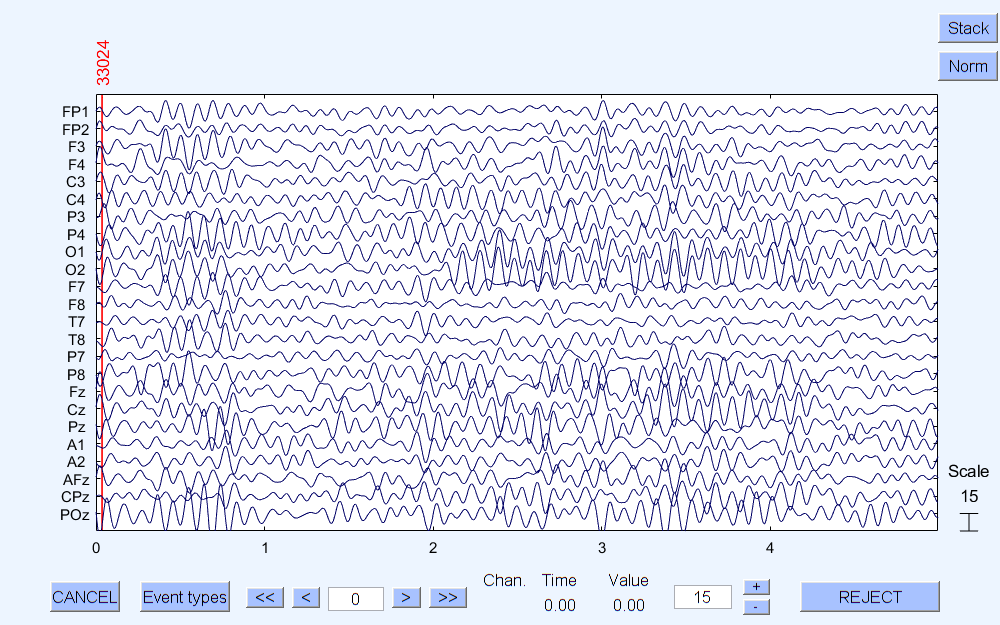

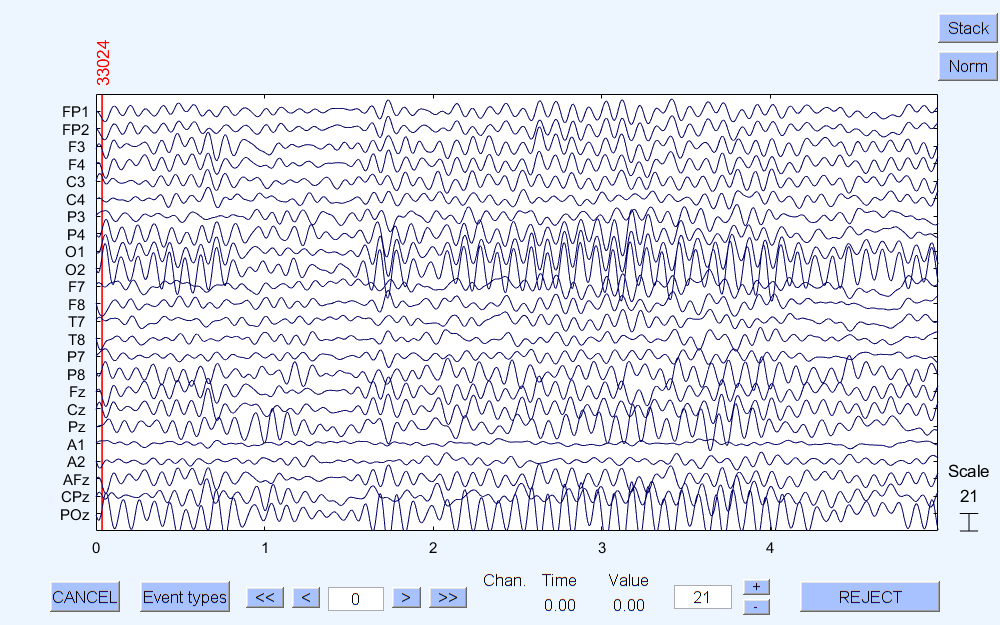

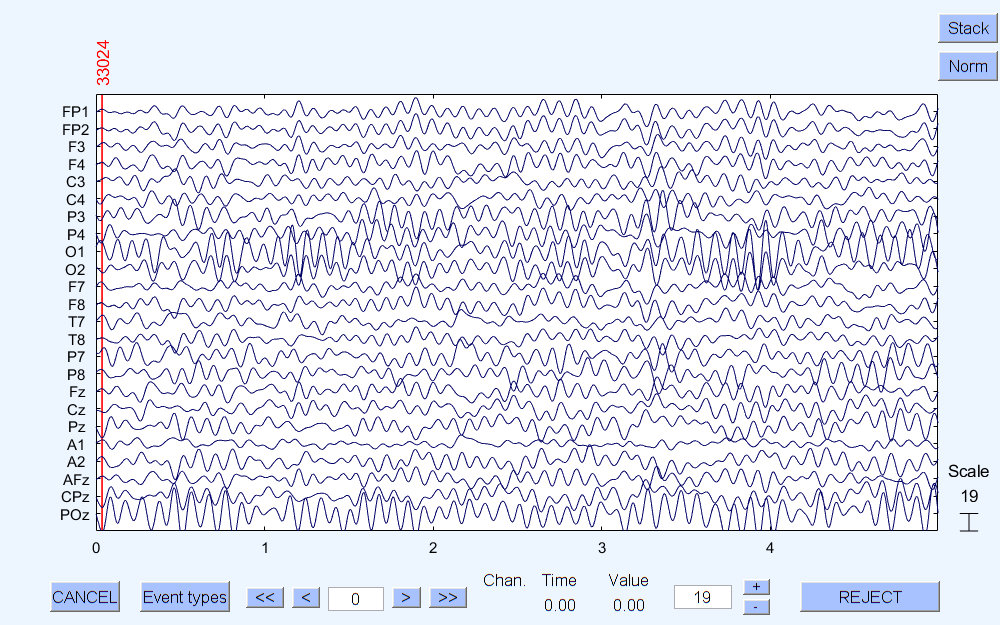

lpfilter = designfilt('lowpassiir','FilterOrder',8, ...
               'HalfPowerFrequency',15, ...
               'DesignMethod','butter','SampleRate',EEG.srate);

% See Magnitude and Phase responses
% fvtool(lpfilter)

for i = 1:1:L
    EEG =[]; EEG = ALLEEG(i);  CURRENTSET = [];  CURRENTSET = i;
    EEG.data = single(filtfilt(lpfilter, double(EEG.data')))'; 
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET); 
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
   pop_eegplot(EEG, 1, 1, 1); 
end

eeglab redraw

**Note:** because of too much computation load, only the data from one participant is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

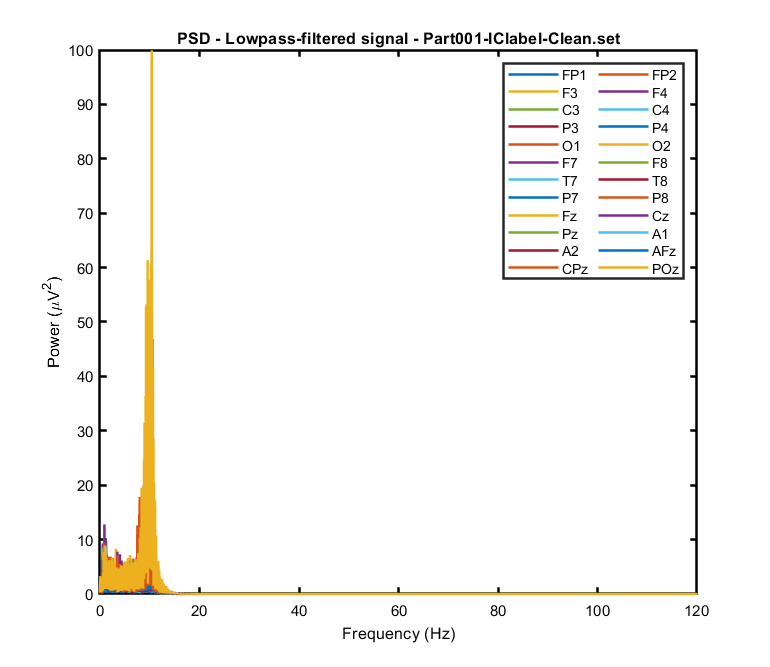

% Plot Power Spectral Density 
for i = 1:1:1%size(ALLEEG,2)
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        [pxx,f] = pwelch(ALLEEG(i).data(j,:),[],[],[],ALLEEG(i).srate);
        plot(f, pxx,LineWidth=1.5)
        hold on 
    end
    xlim([0 120]); EEG =[]; EEG = ALLEEG(i);
    ax = gca;set(ax,'LineWidth',1.5); title(['PSD - Lowpass-filtered signal - ', EEG.setname])
    set(ax, 'XColor', 'k', 'YColor','k'); 
    xlabel('Frequency (Hz)'); ylabel('Power (\muV^2)')
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
       'Location', 'northeast', 'NumColumns', 2)
    set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])
end

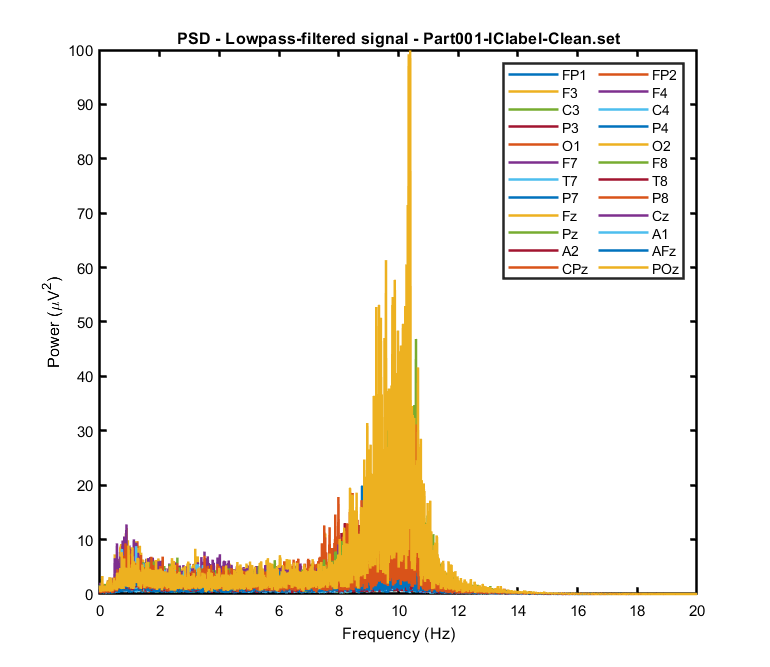


% Zoom on frequencies of interest
for i =1:1:1%size(ALLEEG,2)
    figure("WindowState","maximized")
%     subplot(2,2,i) %Adjust to the number of files
    for j =1:EEG.nbchan
        [pxx,f] = pwelch(ALLEEG(i).data(j,:),[],[],[],ALLEEG(i).srate);
        plot(f, pxx,LineWidth=1.5)
        hold on 
    end
    xlim([0 20]); EEG =[]; EEG = ALLEEG(i);
    ax = gca;set(ax,'LineWidth',1.5); title(['PSD - Lowpass-filtered signal - ', EEG.setname])
    set(ax, 'XColor', 'k', 'YColor','k'); 
    xlabel('Frequency (Hz)'); ylabel('Power (\muV^2)')
    legend(EEG.chanlocs.labels, 'Orientation', 'horizontal',...
       'Location', 'northeast', 'NumColumns', 2)
    set(gcf, "Position", [488.0000  199.4000  649.0000  562.6000])
end

Define single trials based on markers (epochs). Also define the baseline for correction. Here a [-500;-200 ms] baseline is chosen.

rmbase_lim1 = -500 ; rmbase_lim2 = -200; 
EEG_epoched_filt = cell(1,L);

for i = 1:1:L
    EEG =[]; EEG = ALLEEG(i); [types] = eeg_eventtypes(EEG); 
    %Remove event of no interest for ERP extraction
    types(ismember(types,'33024')) = [];
    %Define epochs
    for j = 1:1:size(types,1) %number of onditions defined by the event
        try EEG_ep = pop_epoch(EEG, {types{j,1}}, [-0.5 1]);
            %Baseline correction   
            EEG_epc = pop_rmbase(EEG_ep, [rmbase_lim1 rmbase_lim2] ,[]);
            %Save epoched data in cell
            EEG_epoched_filt{j,i} = EEG_epc;  %conditions x participants
        catch 
            disp('error')
        end
    end
end

pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():240 epochs selected
Epoching...
pop_epoch():240 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


pop_epoch():60 epochs selected
Epoching...
pop_epoch():60 epochs generated
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


**Note:** because of too much computation load, only the data from one participant and one condition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

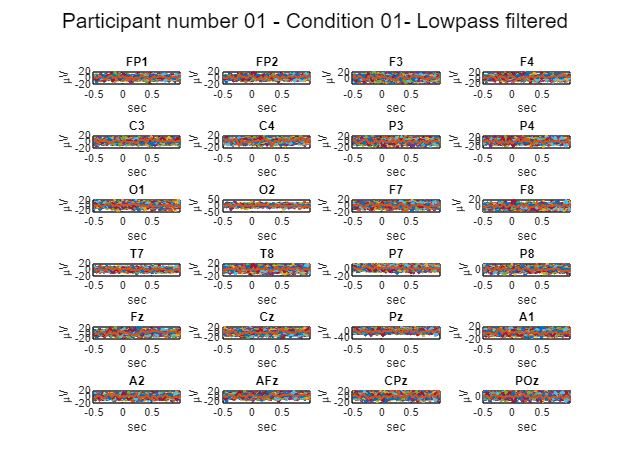

% Plot data per condition and file (participants)/each curve is a trial
% Don't run if too much conditions and participants
for k = 1:1:1%size(EEG_epoched_filt,1) %conditions
    data = EEG_epoched_filt(k,:); EEG_epoched_filt(k,:) = data(~cellfun('isempty',EEG_epoched_filt(k,:))); 
    labels = convertCharsToStrings({EEG.chanlocs.labels});
    for j = 1:1:1%size(EEG_epoched_filt,2)
        figure("WindowState","maximized"); time = EEG_epoched_filt{k,j}.times/1000; %time in sec
        for i = 1:1:EEG_epoched_filt{k,j}.nbchan
            subplot(6,4,i)  %Adjust to the number of channels
            plot(time,squeeze(EEG_epoched_filt{k,j}.data(i,:,:)), LineWidth=1.5)
            title([labels(i)]); 
    %         xlim([-0.5 1]);
            xlabel("sec"); ylabel("\muV")
        end
        sgtitle(['Participant number ', num2str(j,'%02.f'), ...
            ' - Condition ', num2str(k,'%02.f'), '- Lowpass filtered'])
    end
end

Average accross trials

ERP_av_filt = cell(size(EEG_epoched_filt,1),size(EEG_epoched_filt,2));
for k = 1:1:size(EEG_epoched_filt,1) %conditions
    for i = 1:1:size(EEG_epoched_filt,2) %participants
        ERP_ep = [];
        try ERP_ep = mean(EEG_epoched_filt{k,i}.data,3);
            % Save data 
            ERP_av_filt{k,i} = ERP_ep;
        catch 
            disp('error')
        end
    end
end

**Note:** because of too much computation load, only the data from one participant and one condition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

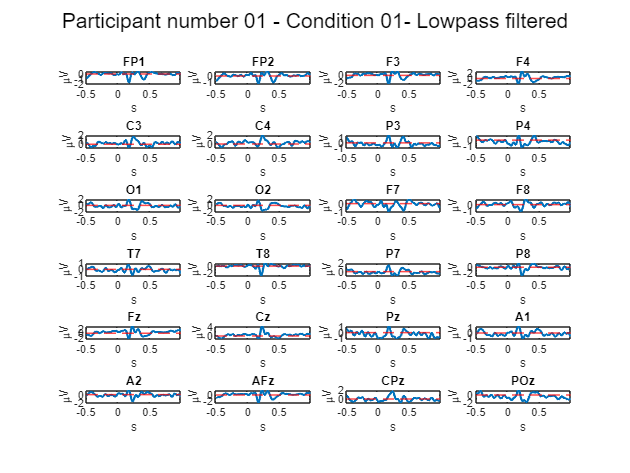

% Plot 
for k = 1:1:1%size(EEG_epoched_filt,1) %conditions
    data = ERP_av_filt(k,:); ERP_av_filt(k,:) = data(~cellfun('isempty',ERP_av_filt(k,:))); 
    for j = 1:1:1%size(ERP_av_filt,2) %participants
        figure("WindowState","maximized")
        for i = 1:1:EEG_epoched_filt{k,j}.nbchan
            subplot(6,4,i)  %Adjust to the number of channels
            plot(time,squeeze(ERP_av_filt{k,j}(i,:)), LineWidth=1.5)
            title([labels(i)]); yline(0, "LineWidth",1, "LineStyle","--", "Color","red");
    %         xlim([-0.5 1]);
            xlabel("s"); ylabel("\muV")
        end
        sgtitle(['Participant number ', num2str(j,'%02.f'), ...
            ' - Condition ', num2str(k,'%02.f'), '- Lowpass filtered'])
    end
end

Average accross participants (grand average)

ERP_av_filt_double=cell(size(ERP_av_filt,1),1);
for k = 1:1:size(ERP_av_filt,1) %conditions
    for i = 1:1:size(ERP_av_filt,2) %participants
        ERP_av_filt_double{k,:}(:,:,i) = cell2mat(ERP_av_filt(k,i));
    end
end

ERP_GA_filt=cell(size(ERP_av_filt,1),1);
for k = 1:1:size(ERP_av_filt_double,1) %conditions
    ERP_GA_filt{k,1} = mean(ERP_av_filt_double{k,:},3);
end

**Note:** because of too much computation load, only the data from one condition is plotted. Please remove corresponding comments in loop and re-run the code in case of needing all the plots. **Also, run the code in the command window to output the figure with correct dimensions for better reading. **

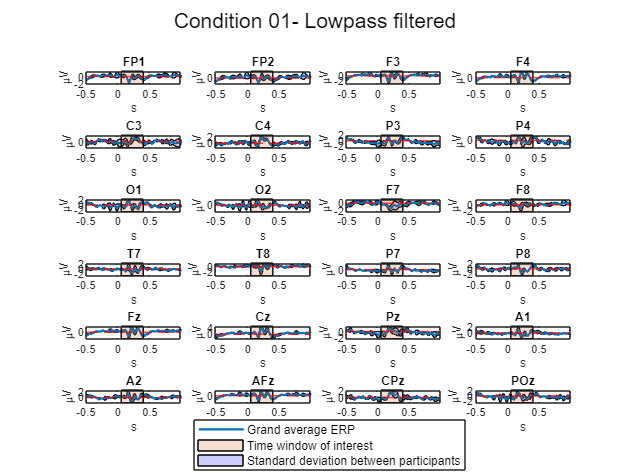

% Plot areas are standard deviations between participants
for k = 1:1:1%size(ERP_GA_filt,1) %conditions
    figure("WindowState","maximized")
    for i = 1:1:EEG_epoched_filt{k,1}.nbchan
        subplot(6,4,i)  % Adjust to the number of channels
        % Standard deviation across participants
        std_dev = std(ERP_av_filt_double{k,1}(i,:,:),0,3); % Along third dimension 
        curvestd1 = (squeeze(ERP_GA_filt{k,1}(i,:))) + std_dev; 
        curvestd2 = (squeeze(ERP_GA_filt{k,1}(i,:))) - std_dev;
        time2 = [time, fliplr(time)];
        inBetween = [curvestd1, fliplr(curvestd2)]; 
        p0=fill(time2, inBetween, 'b', FaceAlpha=0.2);
        hold on;
        p1=plot(time,squeeze(ERP_GA_filt{k,1}(i,:)), LineWidth=1.5); 
        ylim([min(inBetween)-0.2 max(inBetween)+0.2])
        hold on 
        % Patch around time of interest
        y1 = max(inBetween)+0.2; 
        y2 = min(inBetween)-0.2; %Adjust
        x = [0.05 0.4 0.4 0.05]; y = [y2 y2 y1 y1];
        p2=patch(x,y,[0.8500 0.3250 0.0980],'FaceAlpha',0.2);
        title([labels(i)]); yline(0, "LineWidth",1, "LineStyle","--", "Color","red");
%         xlim([-0.5 1]);
        xlabel("s"); ylabel("\muV")
    end
    sgtitle(['Condition ', num2str(k,'%02.f'), '- Lowpass filtered'])
    Lgnd = legend('show', [p1; p2; p0], {'Grand average ERP', ...
        'Time window of interest', 'Standard deviation between participants'});
    Lgnd.Position = [0.445312049605703 0.0296018086066181...
        0.156640627942979 0.0618250553087848];
    Lgnd.FontSize = 8;
end

**Notice: **depending on the experimental paradigm and the aim of the study, ERPs may be averaged according to topography (e.g., frontal right vs frontal left; frontal vs temporal, etc). For statistical analysis, you may extract an index, for instance the magnitude of the ERP peak and/or the latency, per participant, averaged over trials and, if applied, topography. However, both magnitude and latency may vary from one channel to another because of different weights for propagation of the source activity by volume conduction. Therefore, averaging must be considered carefully. 

It is primordial to choose the marker according to the aim of the study. Peak and latency are the most common indexes, however other markers, such a the area under the curve or the fractal dimensionality of the ERP may also be useful to answer the research question. **See the R codes provided for statistical analyses. **

**Also, you may consider cluster-based permutation tests (see the corresponding html file) that allows statistical tests considering all channel:time samples and correcting for multiple testing.  **

*Find peak and latency*

In this exemple, the magnitude of the peak of the N1 component of the grand averaged ERP for "condition 1" at channel F4 will be extracted. 

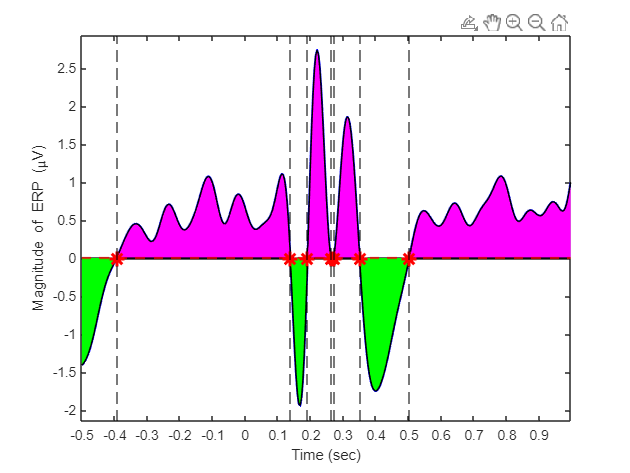

indexF4 = find(~cellfun(@isempty,strfind(labels, 'F4')));
ERP = ERP_GA_filt{1,1}(indexF4,:);

% Plot
figure()
p1=plot(time, ERP, linewidth=1.5, color="blue");
ylim([min(ERP)-0.2 max(ERP)+0.2]); xticks(min(time):0.1:max(time))
yline(0, "LineStyle","--", color = "red", LineWidth=1.5);
hold on
ERPpos = ERP.*(ERP >= 0); ERPneg = ERP .* (ERP <= 0);
p2=area(time, ERPpos, 'FaceColor', 'magenta');
hold on
p3=area(time, ERPneg, 'FaceColor', 'g');
idxLatPos = (find(diff(ERPpos>0)))+1; %indexes of changes
Latency = time(idxLatPos);
p4=plot(Latency, zeros(1,length(Latency)), '*r', 'MarkerSize',10, 'LineWidth',2);
xlim([min(time) max(time)]); xticks(min(time):0.1:max(time))
hold on 
xline(Latency, 'color', 'black', LineWidth=0.5, LineStyle='--');
xlabel("Time (sec)"); ylabel("Magnitude of ERP (\muV)")

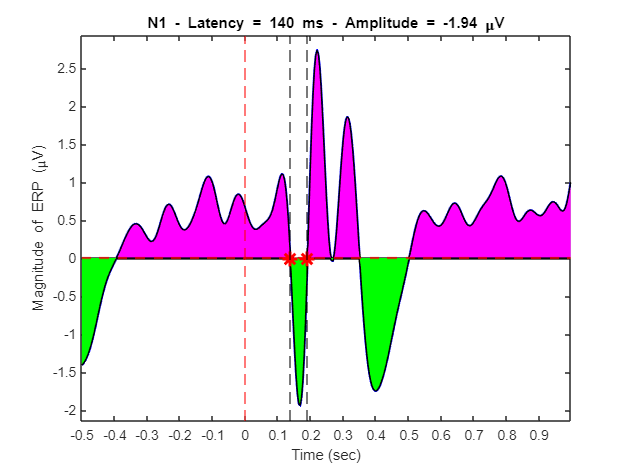


% Latency of N1
LatNegERP = []; LatN1 = [];
for i = 1:1:length(idxLatPos)
    if ERPneg(idxLatPos(i)) <  0 && ERPneg(idxLatPos(i)+1) < 0 %Latencies of all negative ERPs
        LatNegERP = [LatNegERP;time(idxLatPos(i))];
        if time(idxLatPos(i)) < 0.2 && time(idxLatPos(i)) > 0.05 %Latency of N1 (must be between 50 and 200 msec)
            LatN1 = [LatN1;time(idxLatPos(i))];
            idxN1 = i;
        end
    end
end

% Magnitude of N1
[NegERPpeaks, NegERPpeaksIdx]= findpeaks(-ERPneg); NegERPpeaks=-NegERPpeaks;

PeakN1 = [];
for i = 1:1:length(NegERPpeaksIdx)
    if time(NegERPpeaksIdx(i)) < 0.2   && time(NegERPpeaksIdx(i)) > 0.05 %Latency of N1 (must be between 50 and 150 msec)
        PeakN1 = NegERPpeaks(i); % PeakN1 = [PeakN1;ERP(NegERPpeaksIdx(i))];
    end
end

% Plot
figure()
p1=plot(time, ERP, linewidth=1.5, color="blue");
ylim([min(ERP)-0.2 max(ERP)+0.2]); xticks(min(time):0.1:max(time))
yline(0, "LineStyle","--", color = "red", LineWidth=1.5);
hold on
ERPpos = ERP.*(ERP >= 0); ERPneg = ERP .* (ERP <= 0);
p2=area(time, ERPpos, 'FaceColor', 'magenta');
hold on
p3=area(time, ERPneg, 'FaceColor', 'g');
idxLatPos = (find(diff(ERPpos>0)))+1; %indexes of changes
Latency = time(idxLatPos);
p4=plot(Latency([idxN1,idxN1+1]), zeros(1,length([idxN1,idxN1+1])), '*r', 'MarkerSize',10, 'LineWidth',2);
xlim([min(time) max(time)]); xticks(min(time):0.1:max(time))
hold on 
xline(Latency([idxN1,idxN1+1]), 'color', 'black', LineWidth=0.5, LineStyle='--');
hold on 
xlabel("Time (sec)"); ylabel("Magnitude of ERP (\muV)")
xline(0, LineWidth=0.5, color='red', LineStyle='--')
title(['N1 - Latency = ',num2str(LatN1*1000), ' ms - ' 'Amplitude = ' num2str(round(PeakN1,2)), ' \muV'])

**Notice: **Both the amplitude and the latency may depend on the amplitude and latency of the preceding peak and the complexity of the data. So, latency and amplitude may only be compared between conditions of same experimental paradigm when variables that may influence the morphology of the ERP are controlled.  

## Single-Trial ERPs 

Averaging between trials may provided a biased (a ultimately incorrect) output of the ERP, as the single trial waveform vary in magnitude, complexity, and in latency from on trial to another.

See the PowerPoint slide dedicated to it for a detailed explanation (TheoreticalExplanations.pdf). 

Here, data come from a single participant within a file named "Sec1_In". Data were recorded with 16 EEG channels. Data are already epoched into 175 trials of 333 samples. 

**Notice: **This code is automated for several raw files. However, for the sake of simplicty and to decrease computation time, this example preprocesses data from one file only.

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

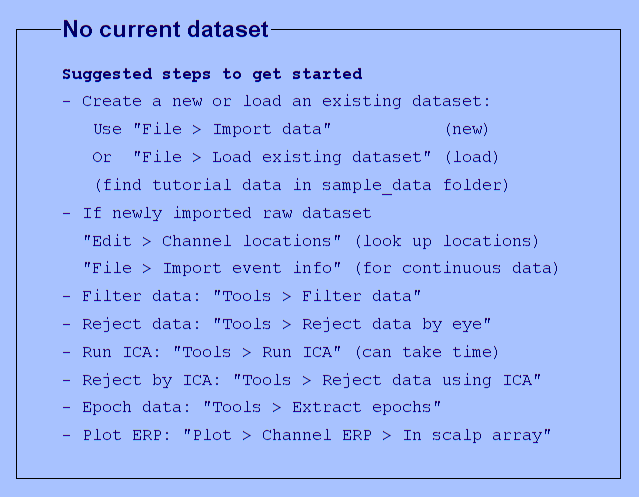

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

*Import previously preprocessed data. Note that the LDA Beameformer algorithm may extract the ERP (compoment) in the presence of noise. Therefore, preprocessing may be reduced to avoid distorsions by any process (e.g., filtering). Please see: *`Treder, M. S., Porbadnigk, A. K., Shahbazi Avarvand, F., Müller, K.-R., & Blankertz, B. (2016). The LDA beamformer: Optimal estimation of ERP source time series using linear discriminant analysis. ``NeuroImage``, ``129``, 279–291. https://doi.org/10.1016/j.neuroimage.2016.01.019`

MainPath = pwd; folder = uigetdir(); 
fileList = dir(fullfile(folder, '*In.set')); L=length(fileList); n = cell(1,L);
for i = 1:L
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name;
   EEG = []; EEG = pop_loadset('filename', fileList(i).name, 'filepath', MainPath);
   EEG.setname = fileList(i).name; CURRENTSET = []; CURRENTSET = i; 
   [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
end

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Sec1_In.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Event-Related-Potentials-ERP\Sec1_In.fdt'...
Scaling components to RMS microvolt


Scaling components to RMS microvolt


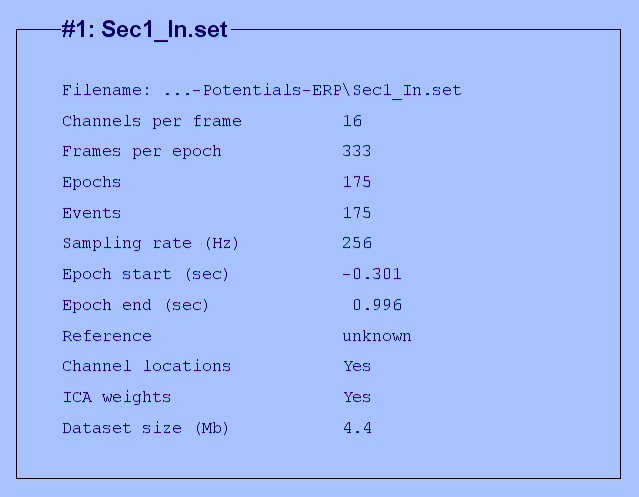

eeglab redraw

Low-pass filter the data at 15 Hz. 

lpfilter = designfilt('lowpassiir','FilterOrder',8, ...
               'HalfPowerFrequency',15, ...
               'DesignMethod','butter','SampleRate',EEG.srate);

% See Magnitude and Phase responses
% fvtool(lpfilter)

EEGP_filtered = cell(1, L); P_filtered= cell(1,L);
for i = 1:1:L
    EEG =[]; EEG = ALLEEG(i);  
    %Load spatial pattern (i.e., average ERP). The pattern is definded within
    %256 samples (1 sec) between -200 and 800 ms around the event. 
    P = []; P = importdata(['Sec' num2str(i) '_InP.mat']);

    %Select portion of the data to be within the same time window as the pattern
    EEGP=EEG.data(:,knnsearch(EEG.times',-200)...
         :knnsearch(EEG.times',798),:); 
    
    % Filter the data
    EEGP_filtered{1,i} = permute(single(filtfilt(lpfilter, ...
            double(permute(EEGP,[2,1,3])))),[2,1,3]); 

    % Filter the spatial pattern
    P_filtered{1,i} = single(filtfilt(lpfilter, double(P')))';
end

The spatial pattern (forward model) is the grand averaged ERP (mean amplitude) centered on the peak of interest. 

In this example, two ERP are extracted: N2 and P3.

%% Pattern (pre-processed and averaged)
time = EEG.times(knnsearch(EEG.times',-200):knnsearch(EEG.times',798));
idx_N2=knnsearch(time', 145):knnsearch(time', 240);  % 145 to 240 ms
idx_P3=knnsearch(time', 245):knnsearch(time', 440);  % 245 to 440 ms

P_N2 = cell(1,L); P_P3 = cell(1,L);
for i = 1:1:L  
    P_N2{1,i}=mean(P_filtered{1,i}(:,idx_N2),2);
    P_P3{1,i}=mean(P_filtered{1,i}(:,idx_P3),2);
end

Extract the source component per epoch and the normalization factor. 

**Note: **please, **run the code in the command window to output the figures with correct dimensions for better reading. **

Processing data with 16 channels and 175 epochs
Epoched data provided. Calculating the covariance across the epochs


Processing data with 16 channels and 175 epochs
Epoched data provided. Calculating the covariance across the epochs


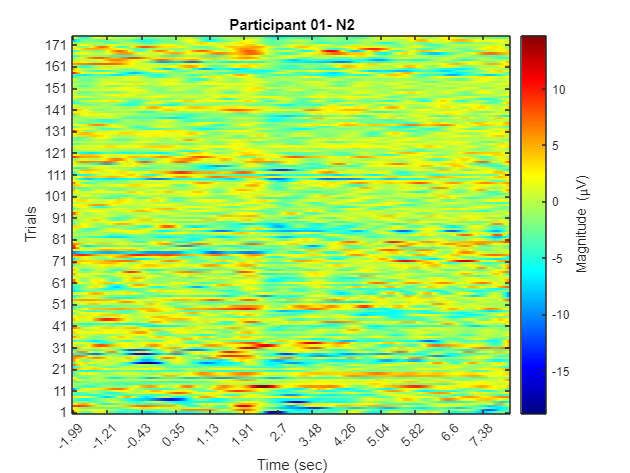

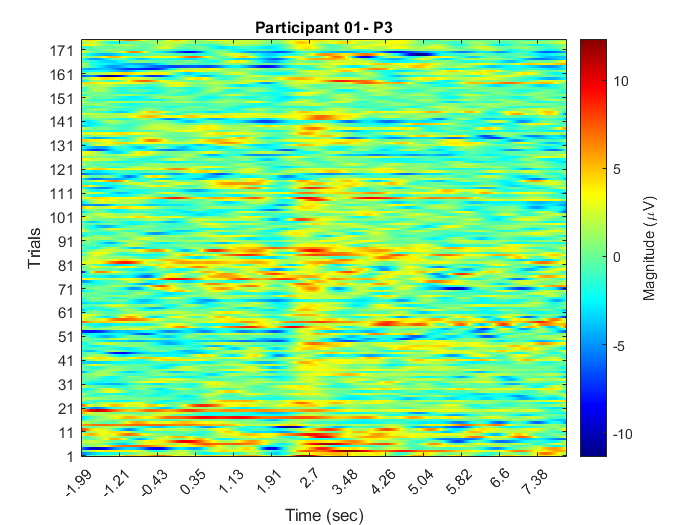

w_N2=cell(1,L); w_P3=cell(1,L); lda_N2=cell(1,L); lda_P3=cell(1,L); 
C_N2=cell(1,L); C_P3=cell(1,L); nor_N2=cell(1,L); nor_P3=cell(1,L); 

for j = 1:1:L
    [w_N2{1,i},lda_N2{1,i},C_N2{1,i},nor_N2{1,i}] = LDAbeamformer(P_N2{1,i},EEGP_filtered{1,i},0.5);
    [w_P3{1,i},lda_P3{1,i},C_P3{1,i},nor_P3{1,i}] = LDAbeamformer(P_P3{1,i},EEGP_filtered{1,i},0.5);
    lda_N2{1,i}=lda_N2{1,i}'; lda_P3{1,i}=lda_P3{1,i}';

    % Plot sources
    % Don't run if too much participants
    figure()
    imagesc(lda_N2{1,i}); set(gca,'YDir','normal');
    yticks(1:10:size(lda_N2{1,i},1)); xticks(1:20:size(lda_N2{1,i},2));
    xticklabels(round(time(1:20:end),0)/100);
    xlabel('Time (sec)', FontSize=10); ylabel('Trials', FontSize=10);
    c=colorbar; c.Label.String ='Magnitude (\muV)'; c.Label.FontSize = 9;
    c2=jet(230); colormap(c2);
    title(['Participant ', num2str(i,'%02.f'), '- N2'])

    figure()
    imagesc(lda_P3{1,i}); set(gca,'YDir','normal');
    yticks(1:10:size(lda_P3{1,i},1)); xticks(1:20:size(lda_P3{1,i},2));
    xticklabels(round(time(1:20:end),0)/100);
    xlabel('Time (sec)', FontSize=10); ylabel('Trials', FontSize=10);
    c=colorbar; c.Label.String ='Magnitude (\muV)';  c.Label.FontSize = 9;
    c2=jet(230); colormap(c2);
    title(['Participant ', num2str(i,'%02.f'), '- P3'])
end

Single-trial extraction

ERPst_1 = []; ERPst = cell(1,L);
for i = 1:1:L
    for j=1:1:size(lda_N2{1,i},1) %trials
        %Spatial pattern * Source * normalization factor
        ERPst_1(:,:,j)=P_P3{1,i}*lda_P3{1,i}(j,:)*nor_P3{1,i}+...
            P_N2{1,i}*lda_N2{1,i}(j,:)*nor_N2{1,i};
    end
    ERPst{1,i} = ERPst_1;
end

Plots

**Note: **please, **run the code in the command window to output the figure with correct dimensions for better reading. **

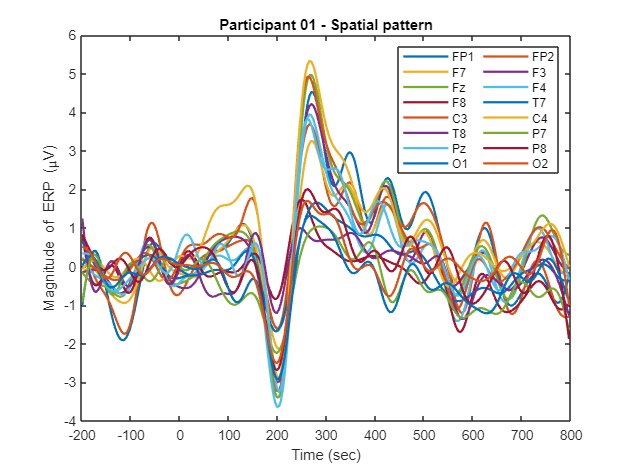

% Spatial pattern
labels = convertCharsToStrings({EEG.chanlocs.labels});
for i = 1:1:size(P_filtered,2)
    figure("WindowState","maximized");
    for j = 1:1:size(P_filtered{1,i},1)
        plot(time,P_filtered{1,i}(j,:), LineWidth=1.5); hold on      
    end
    legend(labels, 'Orientation', 'horizontal',...
           'Location', 'northeast', 'NumColumns', 2)
    title(['Participant ', num2str(i,'%02.f'), ' - Spatial pattern']);
    xlabel("Time (sec)"); ylabel("Magnitude of ERP (\muV)")
end

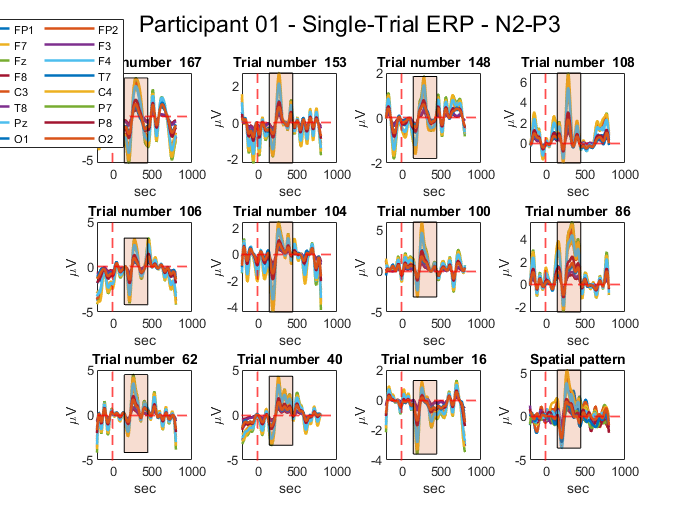

% Single-trial ERP
pl=[167,153,148,108,106,104,100,86,62,40,16];
labels = convertCharsToStrings({EEG.chanlocs.labels});
for i = 1:1:size(ERPst,2) %participant
    figure("WindowState","maximized");
    for j = 1:1:length(pl)+1 %1:1:size(ERPst{1,i},3) %trial
        subplot(3,4,j)        
        if j == length(pl)+1
            plot(time,P_filtered{1,i}(:,:), LineWidth=1.5)
            title('Spatial pattern');
            % Patch around time of interest
            y1 = max(max(P_filtered{1,i}(:,:))); 
            y2 = min(min(P_filtered{1,i}(:,:))); %Adjust
            x = [max(time(idx_P3)) min(time(idx_N2))...
                min(time(idx_N2)) max(time(idx_P3))];
            y = [y2 y2 y1 y1];
            p2=patch(x,y,[0.8500 0.3250 0.0980],'FaceAlpha',0.2);
        else
            plot(time,ERPst{1,i}(:,:,pl(j)), LineWidth=1.5);
            title(['Trial number  ', num2str(pl(j),'%02.f')]);
            y1 = max(max(ERPst{1,i}(:,:,pl(j)))); 
            y2 = min(min(ERPst{1,i}(:,:,pl(j)))); %Adjust
            x = [max(time(idx_P3)) min(time(idx_N2))...
                min(time(idx_N2)) max(time(idx_P3))];
            y = [y2 y2 y1 y1];
            p2=patch(x,y,[0.8500 0.3250 0.0980],'FaceAlpha',0.2);
        end
        xlabel("sec"); ylabel("\muV"); yline(0, "LineWidth",1, "LineStyle","--", "Color","red");
        xline(0, "LineWidth",1, "LineStyle","--", "Color","red");
    end
    sgtitle(['Participant ', num2str(i,'%02.f'), ' - Single-Trial ERP - N2-P3'])
    Lgnd = legend(labels, 'Orientation', 'horizontal', 'NumColumns', 2);
    Lgnd.Position = [0.0107849706554279 0.766532321348488 0.0914062505960465 0.148353135045095];
end